%% Columbia University ELEN E6001 drone control sim
% Author @AlexWei yw4467
% Last modified: Dec. 12, 2025

%% drone params
m = 0.536;          % total mass, kg
g = 9.81;           % gravity, m/s^2
L = 0.1422;         % arm length, m
I = 0.0015;         % moment of inertia about pitch axis, kg*m^2
tau_max = 0.5;      % max pitch torque from differential thrust, N*m

A = [0 1 0 0; 0 0 0 0; 0 0 0 1; g 0 0 0];
B = [0; 1 / I; 0; 0];
C = [1 0 0 0; 0 1 0 0; 0 0 1 0];
D = zeros(3, 1);

rank_O = rank(obsv(A, C))

rank_O = 4

rank_C = rank(ctrb(A, B))

rank_C = 4

rank_A = rank(A)

rank_A = 3

eig_OL = eig(A) % check internal stability

eig_OL =      0
     0
     0
     0


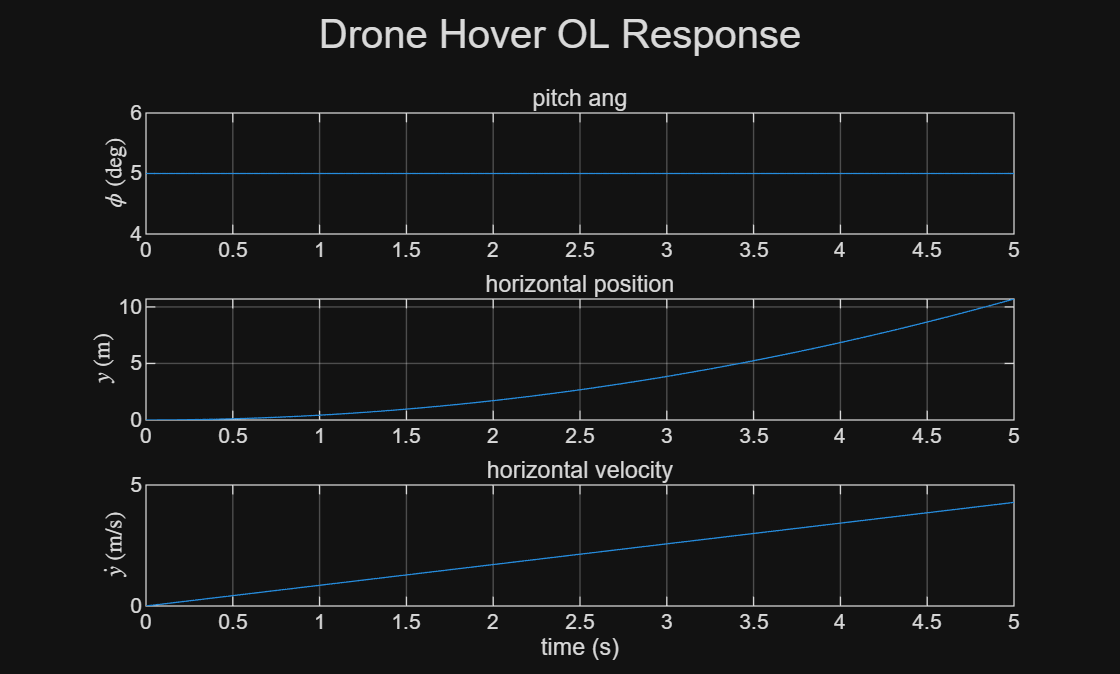


%% OL sys
t = 0 : 0.01 : 5;
u = zeros(size(t));           % no input torque
x = [5 * pi / 180; 0; 0; 0];  % initial state: 5 deg pitch at hover
[y_ol, t_ol, x_ol] = lsim(ss(A, B, C, D), u, t, x);

figure;
subplot(3, 1, 1);
plot(t_ol, x_ol(:, 1) * 180 / pi);
title('pitch ang');
ylabel('$\phi$ (deg)', 'Interpreter', 'latex');
grid on;
subplot(3, 1, 2);
plot(t_ol, x_ol(:, 3));
title('horizontal position');
ylabel('$y$ (m)', 'Interpreter', 'latex');
grid on;
subplot(3, 1, 3);
plot(t_ol, x_ol(:, 4));
title('horizontal velocity');
ylabel('$\dot{y}$ (m/s)', 'Interpreter', 'latex');
xlabel('time (s)');
grid on;
sgtitle('Drone Hover OL Response');

% CL
%% LQR controller design, ideal state fb
Q = diag([100, 1, 10, 1]);
R = 1;
[K_lqr, ~, ~] = lqr(A, B, Q, R)

K_lqr =    12.6659    1.0188    3.1623    3.0275



A1 = A - B * K_lqr;
eig_LQR = eig(A1)

eig_LQR = 1.0e+02 *

  -6.6659 + 0.0000i
  -0.0996 + 0.0000i
  -0.0133 + 0.0116i
  -0.0133 - 0.0116i


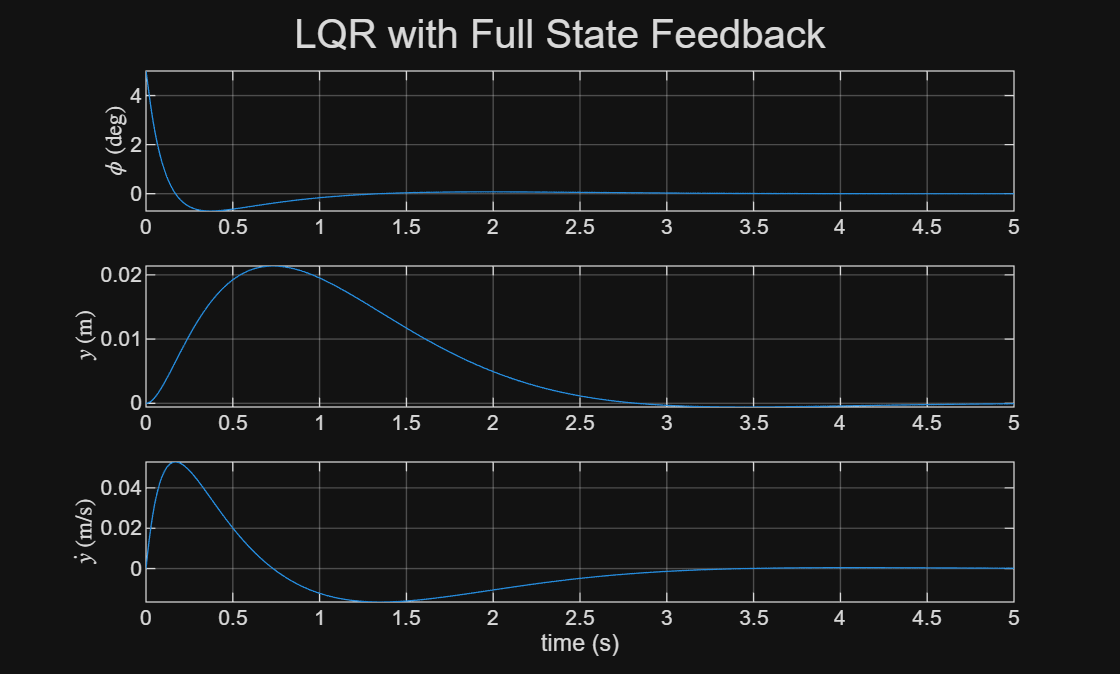

[~, t0, x0] = lsim(ss(A1, B, C, D), u, t, x);

figure;
subplot(3, 1, 1);
plot(t0, x0(:, 1) * 180 / pi);
ylabel('$\phi$ (deg)', 'Interpreter', 'latex');
grid on;
subplot(3, 1, 2);
plot(t0, x0(:, 3));
ylabel('$y$ (m)', 'Interpreter', 'latex');
grid on;
subplot(3, 1, 3);
plot(t0, x0(:, 4));
ylabel('$\dot{y}$ (m/s)', 'Interpreter', 'latex');
xlabel('time (s)');
grid on;
sgtitle('LQR with Full State Feedback');


%% Luenberger observer based LQR [1]
if rank(obsv(A, C)) == size(A, 1)
    L_obs = place(A', C', [-15; -16; -17; -18])' % chosen through t/e on LHP
end

L_obs =    17.0000    1.0000    0.0000
         0   18.0000         0
    0.0000         0   31.0000
    9.8100         0  240.0000



A0 = [A, -B * K_lqr; L_obs * C, A - L_obs * C - B * K_lqr];
B0 = [zeros(size(B)); zeros(size(B))];  % no external input
C0 = [C, zeros(size(C))];               % output y from plant states
D0 = zeros(size(C0, 1), size(B0, 2));
eig_LQR_obs = eig(A0)

eig_LQR_obs = 1.0e+02 *

  -6.6659 + 0.0000i
  -0.0133 + 0.0116i
  -0.0133 - 0.0116i
  -0.0996 + 0.0000i
  -0.1700 + 0.0000i
  -0.1500 + 0.0000i
  -0.1600 + 0.0000i
  -0.1800 + 0.0000i


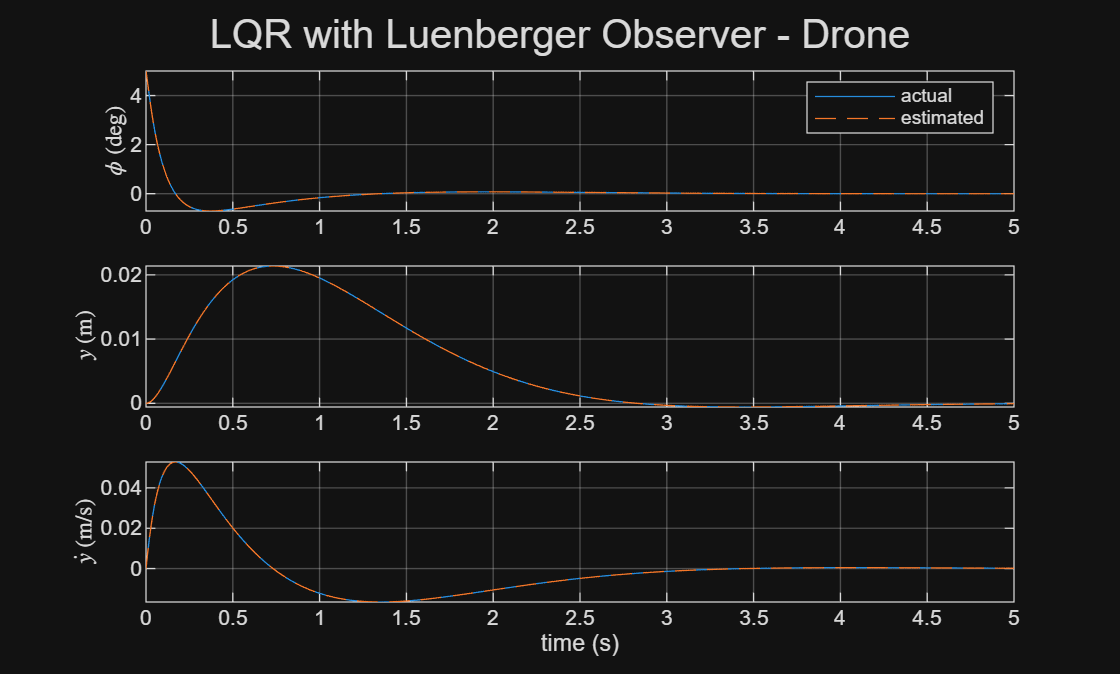


[~, t1, x1] = lsim(ss(A0, B0, C0, D0), u, t, [x; x]);
x1_plt = x1(:, 1:size(A, 1));
x1_hat = x1(:, size(A, 1) + 1:end);

figure;
subplot(3, 1, 1);
plot(t1, x1_plt(:, 1) * 180 / pi);
hold on;
plot(t1, x1_hat(:, 1) * 180 / pi, '--');
ylabel('$\phi$ (deg)', 'Interpreter', 'latex');
grid on;
legend('actual', 'estimated');
subplot(3, 1, 2);
plot(t1, x1_plt(:, 3));
hold on;
plot(t1, x1_hat(:, 3), '--');
ylabel('$y$ (m)', 'Interpreter', 'latex');
grid on;
subplot(3, 1, 3);
plot(t1, x1_plt(:, 4));
hold on;
plot(t1, x1_hat(:, 4), '--');
ylabel('$\dot{y}$ (m/s)', 'Interpreter', 'latex');
xlabel('time (s)');
grid on;
sgtitle('LQR with Luenberger Observer - Drone');

H-infinity controller synthesized with gamma = 0.16081


H-infinity controller K:


                A: [4×4 double]
                B: [4×3 double]
                C: [-201.7813 -0.7820 -10.0504 -20.3335]
                D: [0 0 0]
                E: []
          Offsets: []
           Scaled: 0
        StateName: {4×1 cell}
        StatePath: {4×1 cell}
        StateUnit: {4×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [3×1 double]
      OutputDelay: 0
        InputName: {3×1 cell}
        InputUnit: {3×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



eig_hinf = 1.0e+03 *

  -8.1833 + 0.0000i
  -0.2604 + 0.2575i
  -0.2604 - 0.2575i
  -0.0133 + 0.0000i
  -0.0031 + 0.0000i
  -0.0009 + 0.0000i
  -0.0005 + 0.0005i
  -0.0005 - 0.0005i


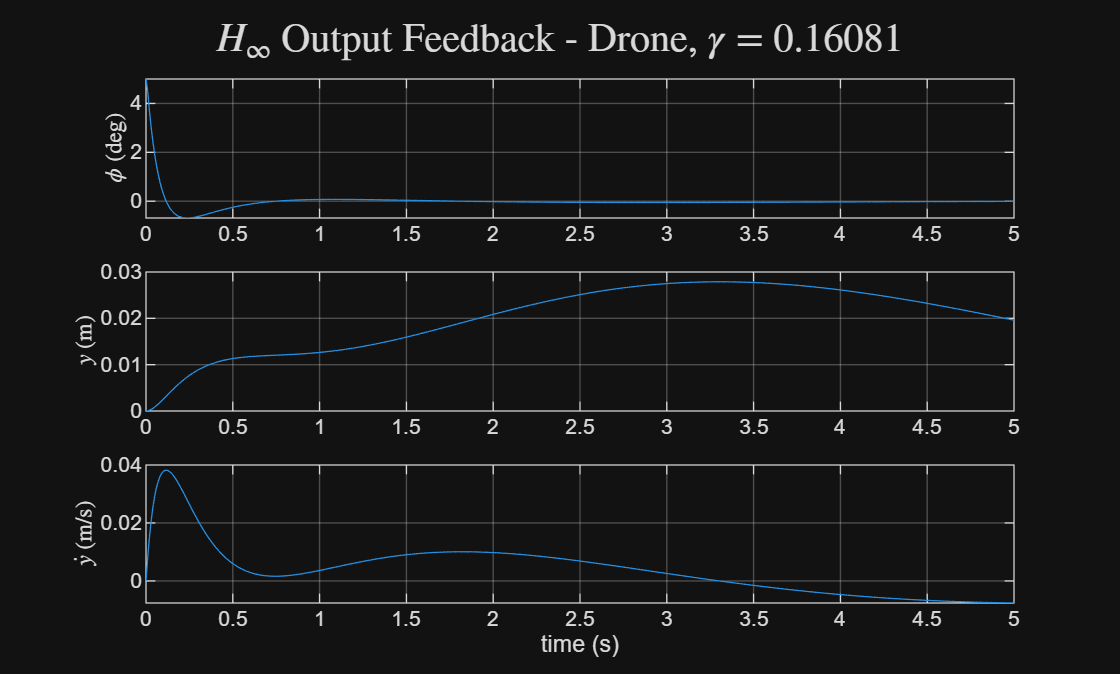


%% H-inf output fb controller design [2]
B1 = B;
B2 = B;
W_phi = 20;   % weight on pitch angle
W_y_pos = 1;  % weight on horizontal position
W_u = 0.1;    % weight on control input
C1 = [W_phi * C(1, :); W_y_pos * C(3, :); zeros(1, size(A, 2))];
D11 = zeros(size(C1, 1), size(B1, 2));
D12 = [0; 0; W_u];
C2 = C;
D21 = zeros(size(C2, 1), size(B1, 2));
D22 = D;

[K, ~, GAM, ~] = hinfsyn(ss(A, [B1, B2], [C1; C2], [D11, D12; D21, D22]), 3, 1, 1, hinfsynOptions('RelTol', 1e-4));
if ~isempty(K) && GAM > 0
    disp(['H-infinity controller synthesized with gamma = ', num2str(GAM)]);
    disp('H-infinity controller K:');
    disp(get(K));

    [Ak, Bk, Ck, Dk] = ssdata(K);
    Ah = [A + B * Dk * C, B * Ck; Bk * C, Ak];
    Bh = zeros(size(Ah, 1), 1);
    Ch = [C, zeros(size(C, 1), size(Ck, 2))];
    Dh = zeros(size(Ch, 1), size(Bh, 2)); 
    eig_hinf = eig(Ah)
    
    [~, t2, x2] = lsim(ss(Ah, Bh, Ch, Dh), u, t, [x; zeros(size(Ak, 1), 1)]);
    x2_plt = x2(:, 1 : size(A, 1));
    
    figure;
    subplot(3, 1, 1);
    plot(t2, x2_plt(:, 1) * 180 / pi);
    ylabel('$\phi$ (deg)', 'Interpreter', 'latex');
    grid on;
    subplot(3, 1, 2);
    plot(t2, x2_plt(:, 3));
    ylabel('$y$ (m)', 'Interpreter', 'latex');
    grid on;
    subplot(3, 1, 3);
    plot(t2, x2_plt(:, 4));
    ylabel('$\dot{y}$ (m/s)', 'Interpreter', 'latex');
    xlabel('time (s)');
    grid on;
    sgtitle(['$H_{\infty}$ Output Feedback - Drone, $\gamma$ = ', num2str(GAM)], 'Interpreter', 'latex');
end

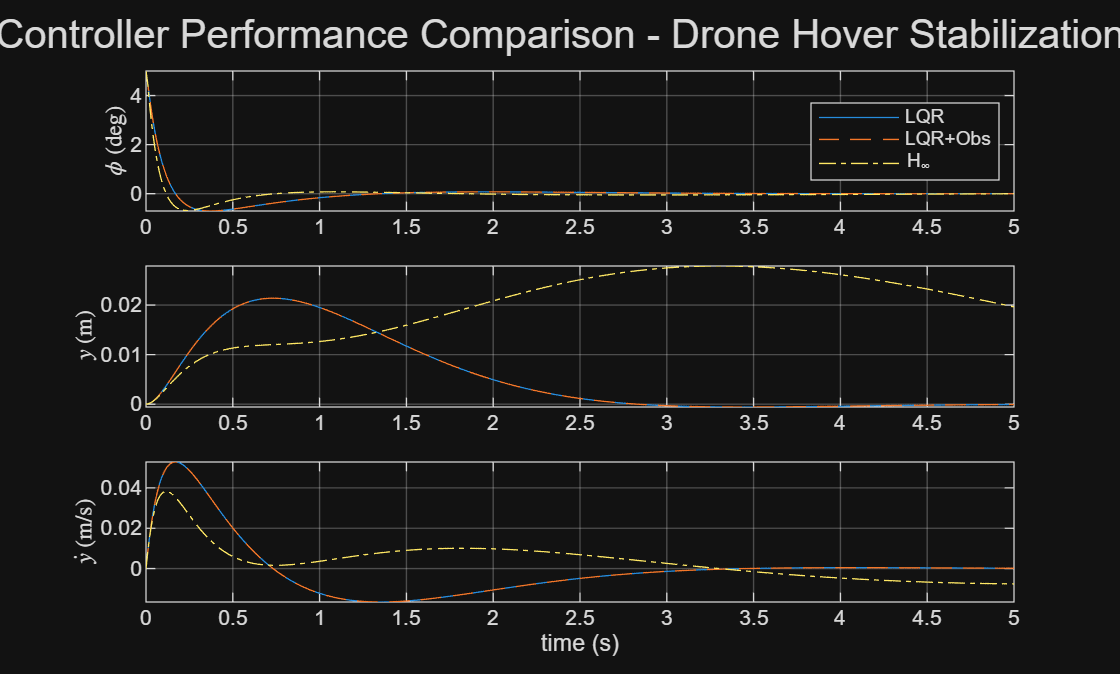


%% comprehensive comparison
figure;
subplot(3, 1, 1);
plot(t0, x0(:, 1) * 180 / pi, '-');
hold on;
plot(t1, x1_plt(:, 1) * 180 / pi, '--');
plot(t2, x2_plt(:, 1) * 180 / pi, '-.');
legend('LQR', 'LQR+Obs', 'H_{\infty}', 'Location', 'best');
ylabel('$\phi$ (deg)', 'Interpreter', 'latex');
grid on;

subplot(3, 1, 2);
plot(t0, x0(:, 3), '-');
hold on;
plot(t1, x1_plt(:, 3), '--');
plot(t2, x2_plt(:, 3), '-.');
ylabel('$y$ (m)', 'Interpreter', 'latex');
grid on;

subplot(3, 1, 3);
plot(t0, x0(:, 4), '-');
hold on;
plot(t1, x1_plt(:, 4), '--');
plot(t2, x2_plt(:, 4), '-.');
ylabel('$\dot{y}$ (m/s)', 'Interpreter', 'latex');
xlabel('time (s)');
grid on;
sgtitle('Controller Performance Comparison - Drone Hover Stabilization');

### References

[1] *Implementation of State Observer in spring Mass damper*. (2023, May 1). Implementation of State Observer in Spring Mass Damper - File Exchange - MATLAB CentralFile Exchange - MATLAB Central. https://ww2.mathworks.cn/matlabcentral/fileexchange/128864-implementation-of-state-observer-in-spring-mass-damper

[2] *F14 H-Infinity Loop-Shaping Design example*. (2022, March 4). F14 H-Infinity Loop-Shaping Design Example - File Exchange - MATLAB CentralFile Exchange - MATLAB Central. https://ww2.mathworks.cn/matlabcentral/fileexchange/50216-f14-h-infinity-loop-shaping-design-example